# Path Following with Obstacle Avoidance in Simulink®

This example shows you how to use Simulink to avoid obstacles while following a path for a differential drive robot. This example uses ROS to send and receive information from a MATLAB®-based simulator. You can replace the simulator with other ROS-based simulators such as Gazebo®.

Prerequisites: [Connect to a ROS-enabled Robot from Simulink](docid:ros_ug.mw_54ffd18b-e10c-4c47-8445-816bf299e5e7)

## Introduction

This example uses a model that implements a path following controller with obstacle avoidance. The controller receives the robot pose and laser scan data from the simulated robot and sends velocity commands to drive the robot on a given path. You can adjust parameters while the model is running and observe the effect on the simulated robot.

## Start a Robot Simulator

Start a simple MATLAB-based simulator:

- Type [`rosinit`](docid:ros_ref.bupf5_j_1) at the MATLAB command line. This creates a local ROS master with network address (URI) of `http://localhost:11311`.

- Type `ExampleHelperSimulinkRobotROS('ObstacleAvoidance')` to start the Robot Simulator. This opens a figure window:

rosinit

Launching ROS Core...
Done in 0.58549 seconds.
Initializing ROS master on http://223.195.36.204:11311.
Initializing global node /matlab_global_node_21291 with NodeURI http://desktop-d6mflhq:59833/ and MasterURI http://localhost:11311.


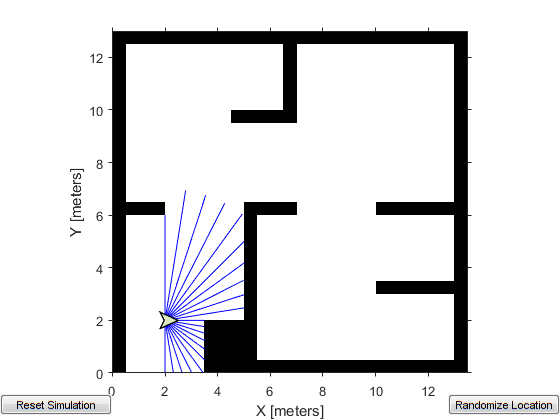

This MATLAB-based simulator is a ROS-based simulator for a differential-drive robot. The simulator receives and sends messages on the following topics:

- It receives velocity commands, as messages of type `geometry_msgs/Twist`, on the `/mobile_base/commands/velocity` topic

- It sends ground truth robot pose information, as messages of type `nav_msgs/Odometry`, to the `/ground_truth_pose` topic

- It sends laser range data, as messages of type `sensor_msgs/LaserScan`, to the `/scan` topic

Replacing the MATLAB-based simulator with Gazebo:

You can also use Gazebo simulator with a simulated TurtleBot®. See [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug.mw_9c45a664-ab3d-48a5-a65a-52913b8532b5) for instructions on setting up the Gazebo environment. See [Connect to a ROS-enabled Robot from Simulink](docid:ros_ug.mw_54ffd18b-e10c-4c47-8445-816bf299e5e7) for instructions on setting up network connection with Gazebo. After starting the virtual machine, launch **Gazebo Office** world using the desktop shortcut. The simulated Turtlebot in the Gazebo simulator, receives velocity commands, as messages of type `geometry_msgs/Twist`, on the `/cmd_vel` topic. You also need a localization algorithm to get robot position in the Gazebo. See [Localize TurtleBot Using Monte Carlo Localization](docid:nav_ug.mw_b8e1b986-db86-4a80-8c62-846b5489a151) for instructions on finding robot location in Gazebo environment.

## Open Existing Model

This [model](matlab:pathFollowingWithObstacleAvoidanceExample) implements the path following with obstacle avoidance algorithm. The model is divided into four subsystems. The following sections explain each subsystem.

이 모델은 장애물 회피 알고리즘을 사용하여 경로 따라가기를 구현합니다. 모델은 4개의 하위 시스템으로 나뉩니다. 다음 섹션에서는 각 하위 시스템에 대해 설명합니다.

open_system('pathFollowingWithObstacleAvoidanceExample');

**Process Inputs**

The 'Inputs' subsystem processes all the inputs to the algorithm.

'입력' 하위 시스템은 알고리즘에 대한 모든 입력을 처리합니다. 

There are two subscribers to receive data from the simulator. The first subscriber receives messages sent on the `/scan` topic. The laser scan message is then processed to extract scan ranges and angles. The second subscriber receives messages sent on the `/ground_truth_pose` topic. The `(x,y)` location and Yaw orientation of the robot is then extracted from the pose message.\

시뮬레이터에서 데이터를 수신하는 두 명의 구독자가 있습니다. 첫 번째 구독자는 /scan 주제에 대해 보낸 메시지를 받습니다. 그런 다음 레이저 스캔 메시지를 처리하여 스캔 범위와 각도를 추출합니다. 두 번째 구독자는 /ground_truth_pose 주제에 대해 보낸 메시지를 받습니다. 

The path is specified as a set of waypoints. This example uses a 3x2 constant input. You can specify any number of waypoints as an Nx2 array. To change the size of the path at run-time, you can either use a variable sized signal or use a fixed size signal with `NaN` padding. This example uses a fixed size input with `NaN` padding for the waypoints that are unknown.

그런 다음 로봇의 (x,y) 위치와 Yaw 방향이 포즈 메시지에서 추출됩니다. 경로는 웨이포인트 세트로 지정됩니다. 이 예에서는 3x2 상수 입력을 사용합니다. 원하는 수의 웨이포인트를 Nx2 배열로 지정할 수 있습니다. 런타임에 경로의 크기를 변경하려면 가변 크기 신호를 사용하거나 NaN 패딩과 함께 고정 크기 신호를 사용할 수 있습니다. 이 예에서는 알 수 없는 웨이포인트에 대해 NaN 패딩이 있는 고정 크기 입력을 사용합니다.

open_system('pathFollowingWithObstacleAvoidanceExample/Inputs','tab');

**Compute Velocity and Heading for Path Following**

The 'Compute Velocity and Heading for Path Following' subsystem computes the linear and angular velocity commands and the target moving direction using the **Pure Pursuit** block. The Pure Pursuit block is located in the **Mobile Robot Algorithms** sub-library within the **Robotics System Toolbox** tab in the Library Browser. Alternatively, you can type `robotalgslib` on the command-line to open the **Mobile Robot Algorithms** sub-library.

You also need to stop the robot once it reaches a goal point. In this example, the goal is the last waypoint on the path. This subsystem also compares the current robot pose and the goal point to determine if the robot is close to the goal.

open_system('pathFollowingWithObstacleAvoidanceExample/Compute Velocity and Heading for Path following','tab');

**Adjust Velocities to Avoid Obstacles**

The 'Adjust Velocities to Avoid Obstacles' subsystem computes adjustments to the linear and angular velocities computed by the path follower.

The Vector Field Histogram block uses the laser range readings to check if the target direction computed using the Pure Pursuit block is obstacle-free or not based on the laser scan data. If there are obstacles along the target direction, the Vector Field Histogram block computes a steering direction that is closest to the target direction and is obstacle-free. The Vector Field Histogram block is also located in the **Mobile Robot Algorithms** sub-library.

The steering direction is `NaN` value when there are no obstacle-free directions in the sensor field of view. In this case, a recovery motion is required, where the robot turns on-the-spot until an obstacle-free direction is available.

Based on the steering direction, this subsystem computes adjustments in linear and angular velocities.

open_system('pathFollowingWithObstacleAvoidanceExample/Adjust Velocities to Avoid Obstacles','tab');

**Send Velocity Commands**

The 'Outputs' subsystem publishes the linear and angular velocities to drive the simulated robot. It adds the velocities computed using the Pure Pursuit path following algorithm with the adjustments computed using the Vector Field Histogram obstacle avoidance algorithm. The final velocities are set on the `geometry_msgs/Twist` message and published on the topic `/mobile_base/commands/velocity`.

This is an enabled subsystem which is triggered when new laser message is received. This means a velocity command is published only when a new sensor information is available. This prevents the robot from hitting the obstacles in case of delay in receiving sensor information.

open_system('pathFollowingWithObstacleAvoidanceExample/Outputs','tab');

**Note: **To use Gazebo simulator, select the `/cmd_vel` topic in the Publish block.

## Configure and Run the Model

Configure and run your model and observe the motion of the robot in the simulator.

- Set simulation Stop time to `Inf`.

- Click the Play button to start simulation. Observe that the robot starts moving in the simulation.

- While the simulation is running, open 'Compute Velocity and Heading for Path Following' subsystem and double-click on the **Pure Pursuit** block. Change the desired linear velocity parameter to `0.5`. Observe increase in the velocity of the robot.

- The default path `[2 2; 8 8]` passes through an obstacle. Observe that the robot takes a detour around the obstacle to reach the end point of the path.

- Open the 'Inputs' subsystem and double-click on the **Waypoints Input** block. Change the constant value from `[2 2;8 8;NaN NaN]` to `[2 2; 8 8; 12 5]`. Notice that robot continues to follow the new path and reaches the new goal point `(12,5)` while avoiding obstacles.

- To stop the simulation, click the Stop button.

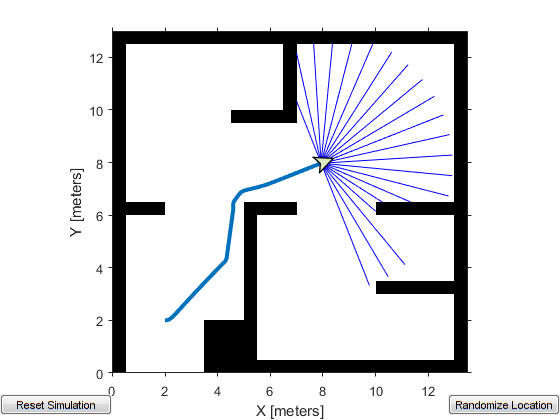

## See Also

- [Generate a Standalone ROS Node from Simulink](docid:ros_ug.mw_6e43b4d9-4810-4e34-84f4-febf1b4c203e)

- [Path Planning in Environments of Different Complexity](docid:robotics_ug#mw_04f9e096-7491-4efd-8380-9d7e178f95b6)

*Copyright 2016 The MathWorks, Inc.*